## Q1-PART-A

%% Q1(a) -- BEMT (trapezoidal inner loop) + root-find for theta75
% Find theta_75 (deg) such that Total Thrust = 300 N for 4 twist cases.
% Uses trapezoidal integration with N points (>=200).

clear; close all; clc;

%% -------------------- Parameters --------------------
rho      = 1.225;        % kg/m^3
Nb       = 2;            % number of blades
R        = 1.0;          % m, blade radius
c_root   = 0.09;         % m, root chord (unless tapered)
C_l_alpha = 5.73;        % per radian
Omega    = 150;          % rad/s
T_target = 300;          % N, hover thrust
x_root   = 0.2;          % root cutout fraction of R (non-dimensional)
% Numerical integration points
N = 400;                 % # of spanwise samples (>=200 recommended)

%% -------------------- radial grid --------------------
x = linspace(x_root, 1, N);     % non-dimensional radius x = r/R
r = x * R;
dr = (1 - x_root) / (N - 1) * R;  % spacing in meters

%% -------------------- helper: local thrust for a given theta75 and case --------------------
% Cases:
% 1 = ideal twist (theta(x) = theta75 * (0.75 ./ x))
% 2 = no twist (theta(x) = theta75)
% 3 = linear twist with tip = theta75 - 15 deg (linear in x, with theta(0.75)=theta75)
% 4 = ideal twist + taper (ctip = 0.5*c_root)

function T = total_thrust_for_theta75(theta75_deg, case_id, x, r, R, c_root, Nb, rho, Omega, C_l_alpha)
    % theta75_deg: reference pitch at x=0.75 (deg)
    theta75_rad = deg2rad(theta75_deg);
    % compute geometric pitch distribution theta(x) in radians, and chord c(x)
    switch case_id
        case 1  % ideal twist
            theta_x = theta75_rad .* (0.75 ./ x);
            c_x = c_root * ones(size(x));
        case 2  % no twist (constant)
            theta_x = theta75_rad * ones(size(x));
            c_x = c_root * ones(size(x));
        case 3  % linear twist: tip = theta75 - 15 deg
            tip_deg = theta75_deg - 15;
            tip_rad = deg2rad(tip_deg);
            % We'll linearly interpolate theta between x_root and 1 so that at x=0.75 => theta75
            % Solve linear line: theta(x) = m*x + b. Enforce theta(0.75)=theta75_rad and theta(1)=tip_rad.
            m = (tip_rad - theta75_rad) / (1 - 0.75);
            b = theta75_rad - m * 0.75;
            theta_x = m .* x + b;
            c_x = c_root * ones(size(x));
        case 4  % ideal twist + taper (ctip = 0.5*c_root)
            theta_x = theta75_rad .* (0.75 ./ x);
            c_tip = 0.5 * c_root;
            % linear taper from root to tip (in x)
            c_x = c_root + (c_tip - c_root) .* ((x - x(1)) ./ (1 - x(1)));
        otherwise
            error('Unknown case id');
    end

    % avoid singularity issues: x should never be zero due to root cutout
    % compute sigma at each x
    sigma_x = Nb .* c_x ./ (pi * R);

    % Pre-allocate
    lambda_x = zeros(size(x));
    Cl_x = zeros(size(x));
    f_x = zeros(size(x));    % dT/dr integrand

    for i = 1:numel(x)
        xi = x(i);
        thetai = theta_x(i);
        sigmai = sigma_x(i);

        % Quadratic coefficients: A*lambda^2 + B*lambda - C = 0
        A = 4 * xi;
        B = 0.5 * sigmai * C_l_alpha * xi;
        C = 0.5 * sigmai * C_l_alpha * xi^2 * thetai;
        disc = B^2 + 4 * A * C;
        if disc < 0
            disc = 0; % numerical safety
        end
        % positive root (physically meaningful)
        lambda_i = (-B + sqrt(disc)) / (2 * A);
        lambda_x(i) = lambda_i;

        % local lift coefficient
        % avoid dividing by zero (xi > 0 because of root cutout)
        Cl_i = C_l_alpha * (thetai - lambda_i / xi);
        Cl_x(i) = Cl_i;

        % local relative velocity magnitude approximated as U = Omega*r (BET assumption)
        % dT/dr = Nb * 0.5 * rho * U^2 * Cl * c(r)
        U2 = (Omega * r(i))^2;
        f_x(i) = 0.5 * rho * Nb * U2 * Cl_i * c_x(i);
    end

    % Integrate f(r) over r using trapezoidal rule to get Total Thrust
    % r array corresponds to x*R
    T = trapz(r, f_x);
end

%% -------------------- Solve for theta75 for each case --------------------
cases = 1:4;
theta75_found = zeros(size(cases));
options = optimset('TolX',1e-6,'Display','off');

for cid = cases
    % root-find in degrees: find theta75 (deg) such that total_thrust - T_target = 0
    fun = @(theta75_deg) total_thrust_for_theta75(theta75_deg, cid, x, r, R, c_root, Nb, rho, Omega, C_l_alpha) - T_target;

    % initial guesses: try a bracket [0, 30] deg, use fzero with a safe starting guess 8 deg
    % Make sure sign change exists; otherwise expand bracket
    a = 0; b = 40; guess = 8;
    fa = fun(a); fb = fun(b);
    if fa * fb > 0
        % expand bracket
        a = -10; b = 60;
    end
    try
        theta75_sol = fzero(fun, guess, options);
    catch
        % fallback to fzero with bracket
        theta75_sol = fzero(fun, [a b], options);
    end
    theta75_found(cid) = theta75_sol;
    fprintf('Case %d: theta75 = %.6f deg -> achieved thrust = %.3f N\n', cid, theta75_sol, ...
        total_thrust_for_theta75(theta75_sol, cid, x, r, R, c_root, Nb, rho, Omega, C_l_alpha));
end

Case 1: theta75 = 6.604289 deg -> achieved thrust = 300.000 N
Case 2: theta75 = 7.106524 deg -> achieved thrust = 300.000 N
Case 3: theta75 = 6.784359 deg -> achieved thrust = 300.000 N
Case 4: theta75 = 8.118183 deg -> achieved thrust = 300.000 N


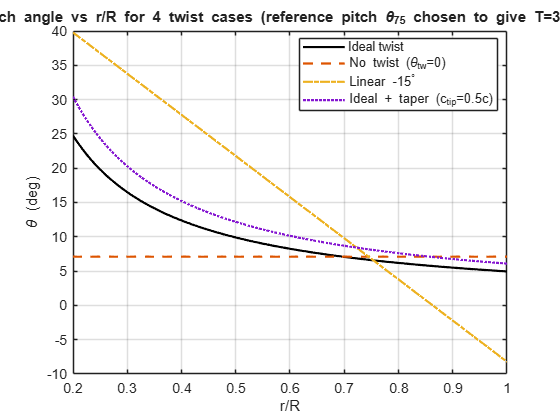


%% -------------------- Compose theta(x) distributions using found theta75 --------------------
theta_deg_cases = zeros(numel(cases), numel(x)); % rows = cases, cols = x

for cid = cases
    theta75_deg = theta75_found(cid);
    switch cid
        case 1
            theta_deg_cases(cid,:) = theta75_deg * (0.75 ./ x);
        case 2
            theta_deg_cases(cid,:) = theta75_deg * ones(size(x));
        case 3
            tip_deg = theta75_deg - 15;
            m = (deg2rad(tip_deg) - deg2rad(theta75_deg)) / (1 - 0.75);
            b = deg2rad(theta75_deg) - m * 0.75;
            theta_rad = m .* x + b;
            theta_deg_cases(cid,:) = rad2deg(theta_rad);
        case 4
            theta_deg_cases(cid,:) = theta75_deg * (0.75 ./ x);
    end
end

%% -------------------- Plot 1: pitch angle vs r/R for all 4 cases --------------------
figure('Name','Pitch distribution (all 4 cases)','NumberTitle','off');
plot(x, theta_deg_cases(1,:), '-k', 'LineWidth', 1.6); hold on;
plot(x, theta_deg_cases(2,:), '--', 'LineWidth', 1.6);
plot(x, theta_deg_cases(3,:), '-.', 'LineWidth', 1.6);
plot(x, theta_deg_cases(4,:), ':', 'LineWidth', 1.6);
xlabel('r/R'); ylabel('\theta (deg)'); grid on;
legend({'Ideal twist','No twist (\theta_{tw}=0)','Linear -15^\circ','Ideal + taper (c_{tip}=0.5c)'}, 'Location','best');
title('Pitch angle vs r/R for 4 twist cases (reference pitch \theta_{75} chosen to give T=300 N)');
xlim([x_root 1]);

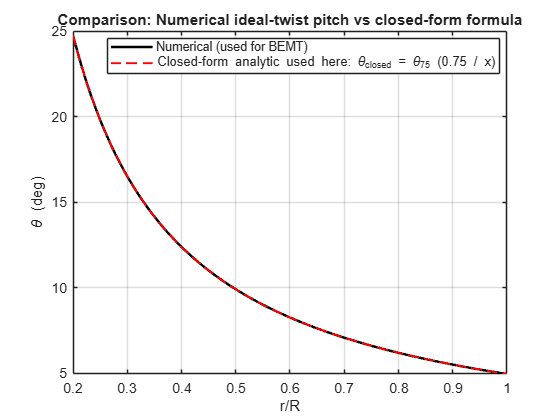


%% -------------------- Plot 2: Numerical ideal twist vs chosen closed-form --------------------
% Closed-form analytic used here: theta_closed(x) = theta75 * (0.75 ./ x)
theta75_case1 = theta75_found(1);
theta_closed = theta75_case1 * (0.75 ./ x);

figure('Name','Ideal twist: numerical vs closed-form','NumberTitle','off');
plot(x, theta_deg_cases(1,:), '-k', 'LineWidth', 1.8); hold on;
plot(x, theta_closed, '--r', 'LineWidth', 1.4);
xlabel('r/R'); ylabel('\theta (deg)'); grid on;
legend({'Numerical (used for BEMT)','Closed-form analytic used here: \theta_{closed} = \theta_{75} (0.75 / x)'}, 'Location','best');
title('Comparison: Numerical ideal-twist pitch vs closed-form formula');
xlim([x_root 1]);


%% -------------------- Print summary --------------------
fprintf('\nSummary of results:\n');


Summary of results:


for cid = cases
    switch cid
        case 1, name = 'Ideal twist';
        case 2, name = 'No twist';
        case 3, name = 'Linear -15 deg';
        case 4, name = 'Ideal + taper';
    end
    fprintf('Case %d (%s): theta75 = %.4f deg\n', cid, name, theta75_found(cid));
end

Case 1 (Ideal twist): theta75 = 6.6043 deg
Case 2 (No twist): theta75 = 7.1065 deg
Case 3 (Linear -15 deg): theta75 = 6.7844 deg
Case 4 (Ideal + taper): theta75 = 8.1182 deg



%% End of script


## Q1-PART-B

%% Q1(b) -- Angle of attack distribution for 4 twist cases (trapezoidal BEMT)
% Single-file script. Helper function calc_total_thrust is defined once at the end.
clear; close all; clc;

%% -------------------- Parameters --------------------
rho       = 1.225;        % kg/m^3
Nb        = 2;            % number of blades
R         = 1.0;          % m, blade radius
c_root    = 0.09;         % m, root chord (unless tapered)
C_l_alpha = 5.73;         % per radian
Omega     = 150;          % rad/s
T_target  = 300;          % N, hover thrust
x_root    = 0.2;          % root cutout fraction of R
N         = 400;          % # of spanwise samples (>=200 recommended)

%% -------------------- radial grid --------------------
x = linspace(x_root, 1, N);     % non-dimensional radius x = r/R
r = x * R;

%% -------------------- Solve for theta75 for each case --------------------
cases = 1:4;
theta75_found = zeros(size(cases));
options = optimset('TolX',1e-6,'Display','off');

for cid = cases
    fun = @(theta75_deg) calc_total_thrust(theta75_deg, cid, x, r, R, c_root, Nb, rho, Omega, C_l_alpha) - T_target;
    % bracket/guess
    a = 0; b = 40; guess = 8;
    fa = fun(a); fb = fun(b);
    if fa * fb > 0
        a = -10; b = 60;
    end
    try
        theta75_sol = fzero(fun, guess, options);
    catch
        theta75_sol = fzero(fun, [a b], options);
    end
    theta75_found(cid) = theta75_sol;
    fprintf('Case %d: theta75 = %.6f deg -> achieved thrust = %.3f N\n', cid, theta75_sol, ...
        calc_total_thrust(theta75_sol, cid, x, r, R, c_root, Nb, rho, Omega, C_l_alpha));
end

Case 1: theta75 = 6.604289 deg -> achieved thrust = 300.000 N
Case 2: theta75 = 7.106524 deg -> achieved thrust = 300.000 N
Case 3: theta75 = 6.784359 deg -> achieved thrust = 300.000 N
Case 4: theta75 = 8.118183 deg -> achieved thrust = 300.000 N


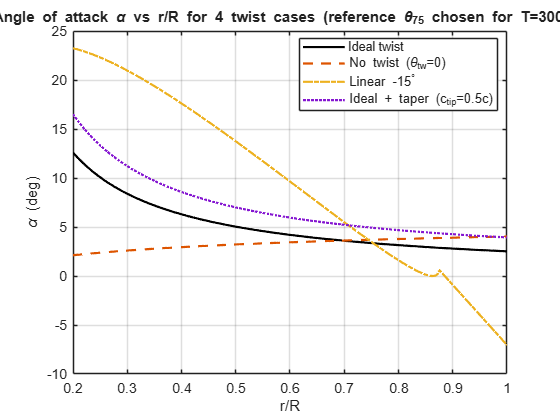


%% -------------------- Compute alpha(x) for each case using local lambda computation --------------------
alpha_deg_cases = zeros(numel(cases), numel(x)); % rows = cases, cols = x

for cid = cases
    theta75_deg = theta75_found(cid);
    % compute theta_x (rad) and chord c_x
    switch cid
        case 1  % ideal twist
            theta_x_rad = deg2rad(theta75_deg) .* (0.75 ./ x);
            c_x = c_root * ones(size(x));
        case 2  % no twist
            theta_x_rad = deg2rad(theta75_deg) * ones(size(x));
            c_x = c_root * ones(size(x));
        case 3  % linear -15 deg
            tip_deg = theta75_deg - 15;
            tip_rad = deg2rad(tip_deg);
            % linear between x=0.75 and x=1 such that theta(0.75)=theta75 and theta(1)=tip
            m = (tip_rad - deg2rad(theta75_deg)) / (1 - 0.75);
            b_lin = deg2rad(theta75_deg) - m * 0.75;
            theta_x_rad = m .* x + b_lin;
            c_x = c_root * ones(size(x));
        case 4  % ideal twist + taper
            theta_x_rad = deg2rad(theta75_deg) .* (0.75 ./ x);
            c_tip = 0.5 * c_root;
            c_x = c_root + (c_tip - c_root) .* ((x - x(1)) ./ (1 - x(1)));
        otherwise
            error('Unknown case id');
    end

    % compute sigma, lambda at each x (quadratic), then alpha = theta - lambda/x
    sigma_x = Nb .* c_x ./ (pi * R);
    lambda_x = zeros(size(x));
    for i = 1:numel(x)
        xi = x(i);
        thetai = theta_x_rad(i);
        sigmai = sigma_x(i);
        A = 4 * xi;
        B = 0.5 * sigmai * C_l_alpha * xi;
        C = 0.5 * sigmai * C_l_alpha * xi^2 * thetai;
        disc = B^2 + 4 * A * C;
        if disc < 0
            disc = 0;
        end
        lambda_i = (-B + sqrt(disc)) / (2 * A);
        lambda_x(i) = lambda_i;
    end

    alpha_rad = theta_x_rad - lambda_x ./ x;   % rad
    alpha_deg_cases(cid, :) = rad2deg(alpha_rad);
end

%% -------------------- Plot: Angle of attack vs r/R (all 4 cases) --------------------
figure('Name','Angle of attack vs r/R (all 4 cases)','NumberTitle','off');
plot(x, alpha_deg_cases(1,:), '-k', 'LineWidth', 1.6); hold on;
plot(x, alpha_deg_cases(2,:), '--', 'LineWidth', 1.6);
plot(x, alpha_deg_cases(3,:), '-.', 'LineWidth', 1.6);
plot(x, alpha_deg_cases(4,:), ':', 'LineWidth', 1.6);
xlabel('r/R'); ylabel('\alpha (deg)'); grid on;
legend({'Ideal twist','No twist (\theta_{tw}=0)','Linear -15^\circ','Ideal + taper (c_{tip}=0.5c)'}, 'Location','best');
title('Angle of attack \alpha vs r/R for 4 twist cases (reference \theta_{75} chosen for T=300 N)');
xlim([x_root 1]);


%% -------------------- Print summary --------------------
fprintf('\nAlpha summary: max/min alpha (deg) for each case:\n');


Alpha summary: max/min alpha (deg) for each case:


for cid = cases
    amax = max(alpha_deg_cases(cid,:));
    amin = min(alpha_deg_cases(cid,:));
    fprintf('Case %d: max = %.3f deg, min = %.3f deg\n', cid, amax, amin);
end

Case 1: max = 12.597 deg, min = 2.519 deg
Case 2: max = 4.029 deg, min = 2.117 deg
Case 3: max = 23.251 deg, min = -7.040 deg
Case 4: max = 16.511 deg, min = 3.937 deg



%% ================= Local function: calc_total_thrust =================
function T = calc_total_thrust(theta75_deg, case_id, x, r, R, c_root, Nb, rho, Omega, C_l_alpha)
    % Compute total thrust using trapezoidal integration of dT/dr for the given case
    theta75_rad = deg2rad(theta75_deg);
    switch case_id
        case 1
            theta_x = theta75_rad .* (0.75 ./ x);
            c_x = c_root * ones(size(x));
        case 2
            theta_x = theta75_rad * ones(size(x));
            c_x = c_root * ones(size(x));
        case 3
            tip_deg = theta75_deg - 15;
            tip_rad = deg2rad(tip_deg);
            m = (tip_rad - theta75_rad) / (1 - 0.75);
            b = theta75_rad - m * 0.75;
            theta_x = m .* x + b;
            c_x = c_root * ones(size(x));
        case 4
            theta_x = theta75_rad .* (0.75 ./ x);
            c_tip = 0.5 * c_root;
            c_x = c_root + (c_tip - c_root) .* ((x - x(1)) ./ (1 - x(1)));
        otherwise
            error('Unknown case id');
    end

    sigma_x = Nb .* c_x ./ (pi * R);
    f_x = zeros(size(x));
    for i = 1:numel(x)
        xi = x(i);
        thetai = theta_x(i);
        sigmai = sigma_x(i);
        A = 4 * xi;
        B = 0.5 * sigmai * C_l_alpha * xi;
        C = 0.5 * sigmai * C_l_alpha * xi^2 * thetai;
        disc = B^2 + 4 * A * C;
        if disc < 0
            disc = 0;
        end
        lambda_i = (-B + sqrt(disc)) / (2 * A);
        Cl_i = C_l_alpha * (thetai - lambda_i / xi);
        U2 = (Omega * r(i))^2;
        f_x(i) = 0.5 * rho * Nb * U2 * Cl_i * c_x(i);  % dT/dr
    end

    T = trapz(r, f_x);
end


## Q1-PART-C

%% Q1(c) -- Induced inflow distribution for 4 twist cases (trapezoidal BEMT)
% Computes theta75 for each case (T_target = 300 N) and plots lambda(r/R)
% Single-file script. Helper function calc_total_thrust_trap is defined at the end.
clear; close all; clc;

%% -------------------- Parameters --------------------
rho       = 1.225;        % kg/m^3
Nb        = 2;            % number of blades
R         = 1.0;          % m, blade radius
c_root    = 0.09;         % m, root chord (unless tapered)
C_l_alpha = 5.73;         % per radian
Omega     = 150;          % rad/s
T_target  = 300;          % N, hover thrust
x_root    = 0.2;          % root cutout fraction of R
N         = 400;          % # of spanwise samples (>=200 recommended)

%% -------------------- radial grid --------------------
x = linspace(x_root, 1, N);     % non-dimensional radius x = r/R
r = x * R;

%% -------------------- Solve for theta75 for each case --------------------
cases = 1:4;
theta75_found = zeros(size(cases));
options = optimset('TolX',1e-6,'Display','off');

for cid = cases
    fun = @(theta75_deg) calc_total_thrust_trap(theta75_deg, cid, x, r, R, c_root, Nb, rho, Omega, C_l_alpha) - T_target;
    % bracket/guess
    a = 0; b = 40; guess = 8;
    fa = fun(a); fb = fun(b);
    if fa * fb > 0
        a = -10; b = 60;
    end
    try
        theta75_sol = fzero(fun, guess, options);
    catch
        theta75_sol = fzero(fun, [a b], options);
    end
    theta75_found(cid) = theta75_sol;
    fprintf('Case %d: theta75 = %.6f deg -> achieved thrust = %.3f N\n', cid, theta75_sol, ...
        calc_total_thrust_trap(theta75_sol, cid, x, r, R, c_root, Nb, rho, Omega, C_l_alpha));
end

Case 1: theta75 = 6.604289 deg -> achieved thrust = 300.000 N
Case 2: theta75 = 7.106524 deg -> achieved thrust = 300.000 N
Case 3: theta75 = 6.784359 deg -> achieved thrust = 300.000 N
Case 4: theta75 = 8.118183 deg -> achieved thrust = 300.000 N


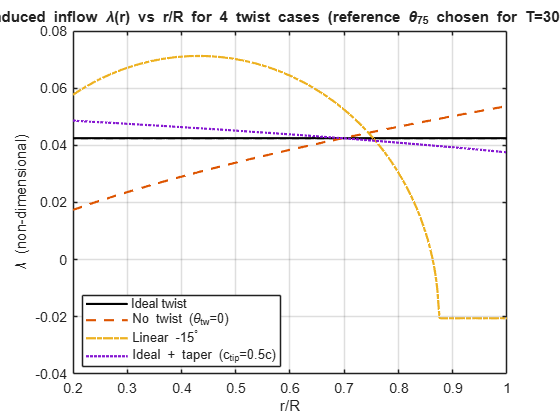


%% -------------------- Compute induced inflow lambda(x) for each case --------------------
lambda_cases = zeros(numel(cases), numel(x)); % rows = cases, cols = x

for cid = cases
    theta75_deg = theta75_found(cid);
    % compute theta_x (rad) and chord c_x
    switch cid
        case 1  % ideal twist
            theta_x_rad = deg2rad(theta75_deg) .* (0.75 ./ x);
            c_x = c_root * ones(size(x));
        case 2  % no twist
            theta_x_rad = deg2rad(theta75_deg) * ones(size(x));
            c_x = c_root * ones(size(x));
        case 3  % linear -15 deg
            tip_deg = theta75_deg - 15;
            tip_rad = deg2rad(tip_deg);
            % linear between x=0.75 and x=1 such that theta(0.75)=theta75 and theta(1)=tip
            m = (tip_rad - deg2rad(theta75_deg)) / (1 - 0.75);
            b_lin = deg2rad(theta75_deg) - m * 0.75;
            theta_x_rad = m .* x + b_lin;
            c_x = c_root * ones(size(x));
        case 4  % ideal twist + taper
            theta_x_rad = deg2rad(theta75_deg) .* (0.75 ./ x);
            c_tip = 0.5 * c_root;
            c_x = c_root + (c_tip - c_root) .* ((x - x(1)) ./ (1 - x(1)));
        otherwise
            error('Unknown case id');
    end

    % compute sigma, lambda at each x using the quadratic solution
    sigma_x = Nb .* c_x ./ (pi * R);
    lambda_x = zeros(size(x));
    for i = 1:numel(x)
        xi = x(i);
        thetai = theta_x_rad(i);
        sigmai = sigma_x(i);
        A = 4 * xi;
        B = 0.5 * sigmai * C_l_alpha * xi;
        C = 0.5 * sigmai * C_l_alpha * xi^2 * thetai;
        disc = B^2 + 4 * A * C;
        if disc < 0
            disc = 0;
        end
        % physically meaningful positive root
        lambda_i = (-B + sqrt(disc)) / (2 * A);
        lambda_x(i) = lambda_i;
    end

    lambda_cases(cid, :) = lambda_x;
end

%% -------------------- Plot: Induced inflow lambda vs r/R (all 4 cases) --------------------
figure('Name','Induced inflow \lambda vs r/R (all 4 cases)','NumberTitle','off');
plot(x, lambda_cases(1,:), '-k', 'LineWidth', 1.6); hold on;
plot(x, lambda_cases(2,:), '--', 'LineWidth', 1.6);
plot(x, lambda_cases(3,:), '-.', 'LineWidth', 1.6);
plot(x, lambda_cases(4,:), ':', 'LineWidth', 1.6);
xlabel('r/R'); ylabel('\lambda (non-dimensional)'); grid on;
legend({'Ideal twist','No twist (\theta_{tw}=0)','Linear -15^\circ','Ideal + taper (c_{tip}=0.5c)'}, 'Location','best');
title('Induced inflow \lambda(r) vs r/R for 4 twist cases (reference \theta_{75} chosen for T=300 N)');
xlim([x_root 1]);


%% -------------------- Print summary --------------------
fprintf('\nLambda summary: at x=0.75 and global min/max for each case:\n');


Lambda summary: at x=0.75 and global min/max for each case:


[~, idx75] = min(abs(x - 0.75));
for cid = cases
    l75 = lambda_cases(cid, idx75);
    lmax = max(lambda_cases(cid,:));
    lmin = min(lambda_cases(cid,:));
    fprintf('Case %d: lambda(0.75)=%.5f, max=%.5f, min=%.5f\n', cid, l75, lmax, lmin);
end

Case 1: lambda(0.75)=0.04248, max=0.04248, min=0.04248
Case 2: lambda(0.75)=0.04456, max=0.05372, min=0.01742
Case 3: lambda(0.75)=0.04338, max=0.07126, min=-0.02052
Case 4: lambda(0.75)=0.04171, max=0.04863, min=0.03755



%% ================= Local function: calc_total_thrust_trap =================
function T = calc_total_thrust_trap(theta75_deg, case_id, x, r, R, c_root, Nb, rho, Omega, C_l_alpha)
    % Compute total thrust using trapezoidal integration of dT/dr for the given case
    theta75_rad = deg2rad(theta75_deg);
    switch case_id
        case 1
            theta_x = theta75_rad .* (0.75 ./ x);
            c_x = c_root * ones(size(x));
        case 2
            theta_x = theta75_rad * ones(size(x));
            c_x = c_root * ones(size(x));
        case 3
            tip_deg = theta75_deg - 15;
            tip_rad = deg2rad(tip_deg);
            m = (tip_rad - theta75_rad) / (1 - 0.75);
            b = theta75_rad - m * 0.75;
            theta_x = m .* x + b;
            c_x = c_root * ones(size(x));
        case 4
            theta_x = theta75_rad .* (0.75 ./ x);
            c_tip = 0.5 * c_root;
            c_x = c_root + (c_tip - c_root) .* ((x - x(1)) ./ (1 - x(1)));
        otherwise
            error('Unknown case id');
    end

    sigma_x = Nb .* c_x ./ (pi * R);
    f_x = zeros(size(x));
    for i = 1:numel(x)
        xi = x(i);
        thetai = theta_x(i);
        sigmai = sigma_x(i);
        A = 4 * xi;
        B = 0.5 * sigmai * C_l_alpha * xi;
        C = 0.5 * sigmai * C_l_alpha * xi^2 * thetai;
        disc = B^2 + 4 * A * C;
        if disc < 0
            disc = 0;
        end
        lambda_i = (-B + sqrt(disc)) / (2 * A);
        Cl_i = C_l_alpha * (thetai - lambda_i / xi);
        U2 = (Omega * r(i))^2;
        f_x(i) = 0.5 * rho * Nb * U2 * Cl_i * c_x(i);  % dT/dr
    end

    T = trapz(r, f_x);
end


## Q1-PART-D

%% Q1(d) -- Thrust & Torque distributions (trapezoidal BEMT)
% Produces:
%  1) dC_T/dr vs r/R (all 4 twist cases)
%  2) cumulative C_Q(r) vs r/R (total torque coefficient)
%  3) cumulative C_Qi(r) vs r/R (induced torque coefficient)
%  4) cumulative C_Qp(r) vs r/R (profile torque coefficient)
%
% Conventions used:
%  A = pi*R^2
%  C_T = T / (rho * A * (Omega*R)^2)
%  C_Q = Q / (rho * A * (Omega*R)^2 * R)
% See MathWorks rotor docs and rotor aerodynamics notes. :contentReference[oaicite:2]{index=2}

clear; close all; clc;

%% -------------------- Parameters --------------------
rho       = 1.225;        % kg/m^3
Nb        = 2;            % number of blades
R         = 1.0;          % m, blade radius
c_root    = 0.09;         % m, root chord (unless tapered)
C_l_alpha = 5.73;         % per radian
Omega     = 150;          % rad/s
T_target  = 300;          % N, hover thrust
Cdo       = 0.01;         % profile drag coefficient (given)
x_root    = 0.2;          % root cutout fraction of R
N         = 400;          % # of spanwise samples (>=200 recommended)

A = pi * R^2;             % rotor disk area
denom_CT = rho * A * (Omega * R)^2;            % denominator for CT
denom_CQ = rho * A * (Omega * R)^2 * R;        % denominator for CQ

%% -------------------- radial grid --------------------
x = linspace(x_root, 1, N);     % nondimensional radius
r = x * R;
dr = r(2) - r(1);

%% -------------------- Solve for theta75 for each case --------------------
cases = 1:4;
theta75_found = zeros(size(cases));
options = optimset('TolX',1e-6,'Display','off');

for cid = cases
    fun = @(theta75_deg) calc_total_thrust_dist(theta75_deg, cid, x, r, R, c_root, Nb, rho, Omega, C_l_alpha, Cdo) - T_target;
    a = 0; b = 40; guess = 8;
    fa = fun(a); fb = fun(b);
    if fa * fb > 0
        a = -10; b = 60;
    end
    try
        theta75_sol = fzero(fun, guess, options);
    catch
        theta75_sol = fzero(fun, [a b], options);
    end
    theta75_found(cid) = theta75_sol;
    fprintf('Case %d: theta75 = %.6f deg -> achieved thrust = %.3f N\n', cid, theta75_sol, ...
        calc_total_thrust_dist(theta75_sol, cid, x, r, R, c_root, Nb, rho, Omega, C_l_alpha, Cdo));
end

Case 1: theta75 = 6.604289 deg -> achieved thrust = 300.000 N
Case 2: theta75 = 7.106524 deg -> achieved thrust = 300.000 N
Case 3: theta75 = 6.784359 deg -> achieved thrust = 300.000 N
Case 4: theta75 = 8.118183 deg -> achieved thrust = 300.000 N


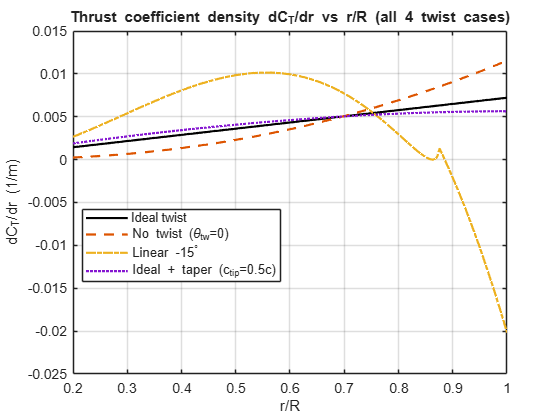


%% -------------------- For each case compute per-span distributions --------------------
% Preallocate
dTdr_cases = zeros(numel(cases), numel(x));    % dT/dr (N per m)
lambda_cases = zeros(numel(cases), numel(x));  % induced inflow lambda (non-dim)
dQpdr_cases = zeros(numel(cases), numel(x));   % profile torque density (N*m per m)
dQidr_cases = zeros(numel(cases), numel(x));   % induced torque density (N*m per m)

for cid = cases
    theta75_deg = theta75_found(cid);
    % compute theta_x (rad) and chord c_x
    switch cid
        case 1  % ideal twist
            theta_x_rad = deg2rad(theta75_deg) .* (0.75 ./ x);
            c_x = c_root * ones(size(x));
        case 2  % no twist
            theta_x_rad = deg2rad(theta75_deg) * ones(size(x));
            c_x = c_root * ones(size(x));
        case 3  % linear -15 deg
            tip_deg = theta75_deg - 15;
            tip_rad = deg2rad(tip_deg);
            m = (tip_rad - deg2rad(theta75_deg)) / (1 - 0.75);
            b_lin = deg2rad(theta75_deg) - m * 0.75;
            theta_x_rad = m .* x + b_lin;
            c_x = c_root * ones(size(x));
        case 4  % ideal twist + taper
            theta_x_rad = deg2rad(theta75_deg) .* (0.75 ./ x);
            c_tip = 0.5 * c_root;
            c_x = c_root + (c_tip - c_root) .* ((x - x(1)) ./ (1 - x(1)));
        otherwise
            error('Unknown case id');
    end

    sigma_x = Nb .* c_x ./ (pi * R);

    % compute local lambda and dT/dr
    for i = 1:numel(x)
        xi = x(i);
        thetai = theta_x_rad(i);
        sigmai = sigma_x(i);

        % Solve quadratic A lambda^2 + B lambda - C = 0
        Acoef = 4 * xi;
        Bcoef = 0.5 * sigmai * C_l_alpha * xi;
        Ccoef = 0.5 * sigmai * C_l_alpha * xi^2 * thetai;
        disc = Bcoef^2 + 4 * Acoef * Ccoef;
        if disc < 0
            disc = 0;
        end
        lambda_i = (-Bcoef + sqrt(disc)) / (2 * Acoef);
        lambda_cases(cid,i) = lambda_i;

        % local Cl
        Cl_i = C_l_alpha * (thetai - lambda_i / xi);

        % dT/dr (Blade element lift contribution)
        U2 = (Omega * r(i))^2;
        dTdr = 0.5 * rho * Nb * U2 * Cl_i * c_x(i);   % N per meter
        dTdr_cases(cid,i) = dTdr;

        % profile torque density: dQp/dr = r * (0.5 rho Nb U^2 c Cd)
        dQpdr_cases(cid,i) = r(i) * (0.5 * rho * Nb * U2 * c_x(i) * Cdo);  % N*m per m

        % induced torque density: dQi/dr = (dT/dr) * lambda * R
        dQidr_cases(cid,i) = dTdr * lambda_i * R;  % N*m per m
    end
end

%% -------------------- Convert to non-dimensional densities / cumulative coefficients --------------------
% dC_T/dr (non-dimensional per m) and its cumulative CT(r)
dCTdr_cases = dTdr_cases ./ denom_CT;          % nondim per meter
CT_cum_cases = zeros(size(dCTdr_cases));      % cumulative CT from root to r

% torque coef densities and cumulative
dCqdr_cases = (dQpdr_cases + dQidr_cases) ./ denom_CQ;   % total dCq/dr (nondim per m)
Cq_cum_cases = zeros(size(dCqdr_cases));
dCqpi_dr_cases = dQidr_cases ./ denom_CQ;    % induced torque coeff density
Cqi_cum_cases = zeros(size(dCqpi_dr_cases));
dCqp_dr_cases = dQpdr_cases ./ denom_CQ;     % profile torque coeff density
Cqp_cum_cases = zeros(size(dCqp_dr_cases));

for cid = cases
    % cumulative via trapezoid (integrate from root to each radius)
    CT_cum_cases(cid,:) = cumtrapz(r, dCTdr_cases(cid,:));
    Cq_cum_cases(cid,:) = cumtrapz(r, dCqdr_cases(cid,:));
    Cqi_cum_cases(cid,:) = cumtrapz(r, dCqpi_dr_cases(cid,:));
    Cqp_cum_cases(cid,:) = cumtrapz(r, dCqp_dr_cases(cid,:));
end

%% -------------------- Plot 1: dC_T/dr vs r/R (all 4 cases) --------------------
figure('Name','dC_T/dr vs r/R (all 4 cases)','NumberTitle','off');
plot(x, dCTdr_cases(1,:), '-k', 'LineWidth', 1.6); hold on;
plot(x, dCTdr_cases(2,:), '--', 'LineWidth', 1.6);
plot(x, dCTdr_cases(3,:), '-.', 'LineWidth', 1.6);
plot(x, dCTdr_cases(4,:), ':', 'LineWidth', 1.6);
xlabel('r/R'); ylabel('dC_T/dr (1/m)'); grid on;
legend({'Ideal twist','No twist (\theta_{tw}=0)','Linear -15^\circ','Ideal + taper (c_{tip}=0.5c)'}, 'Location','best');
title('Thrust coefficient density dC_T/dr vs r/R (all 4 twist cases)');
xlim([x_root 1]);

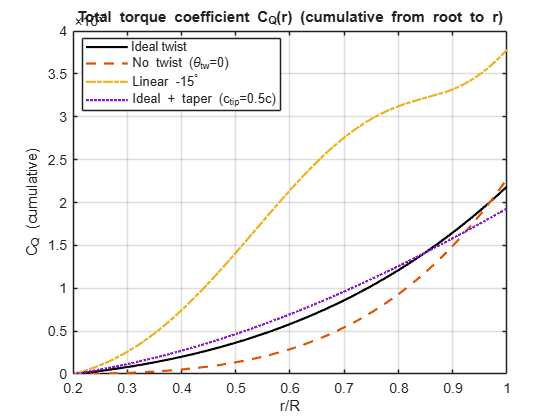


%% -------------------- Plot 2: Total cumulative C_Q(r) vs r/R --------------------
figure('Name','Total C_Q(r) vs r/R (all 4 cases)','NumberTitle','off');
plot(x, Cq_cum_cases(1,:), '-k', 'LineWidth', 1.6); hold on;
plot(x, Cq_cum_cases(2,:), '--', 'LineWidth', 1.6);
plot(x, Cq_cum_cases(3,:), '-.', 'LineWidth', 1.6);
plot(x, Cq_cum_cases(4,:), ':', 'LineWidth', 1.6);
xlabel('r/R'); ylabel('C_Q (cumulative)'); grid on;
legend({'Ideal twist','No twist (\theta_{tw}=0)','Linear -15^\circ','Ideal + taper (c_{tip}=0.5c)'}, 'Location','best');
title('Total torque coefficient C_Q(r) (cumulative from root to r)');
xlim([x_root 1]);

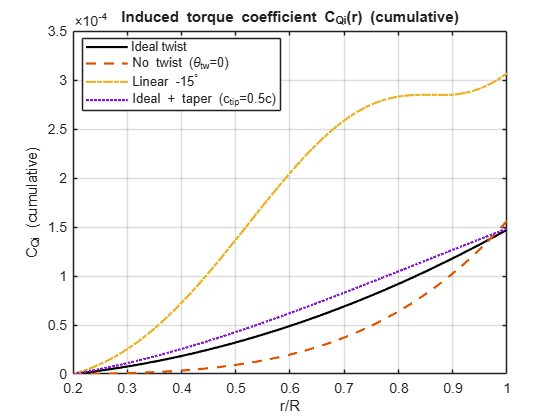


%% -------------------- Plot 3: Induced torque coefficient C_Qi(r) vs r/R --------------------
figure('Name','Induced C_Qi(r) vs r/R (all 4 cases)','NumberTitle','off');
plot(x, Cqi_cum_cases(1,:), '-k', 'LineWidth', 1.6); hold on;
plot(x, Cqi_cum_cases(2,:), '--', 'LineWidth', 1.6);
plot(x, Cqi_cum_cases(3,:), '-.', 'LineWidth', 1.6);
plot(x, Cqi_cum_cases(4,:), ':', 'LineWidth', 1.6);
xlabel('r/R'); ylabel('C_{Qi} (cumulative)'); grid on;
legend({'Ideal twist','No twist (\theta_{tw}=0)','Linear -15^\circ','Ideal + taper (c_{tip}=0.5c)'}, 'Location','best');
title('Induced torque coefficient C_{Qi}(r) (cumulative)');
xlim([x_root 1]);

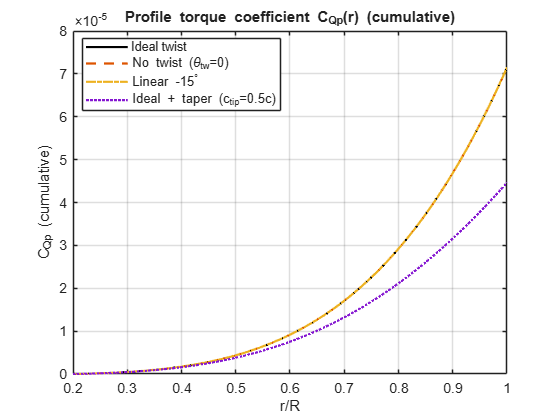


%% -------------------- Plot 4: Profile torque coefficient C_Qp(r) vs r/R --------------------
figure('Name','Profile C_Qp(r) vs r/R (all 4 cases)','NumberTitle','off');
plot(x, Cqp_cum_cases(1,:), '-k', 'LineWidth', 1.6); hold on;
plot(x, Cqp_cum_cases(2,:), '--', 'LineWidth', 1.6);
plot(x, Cqp_cum_cases(3,:), '-.', 'LineWidth', 1.6);
plot(x, Cqp_cum_cases(4,:), ':', 'LineWidth', 1.6);
xlabel('r/R'); ylabel('C_{Qp} (cumulative)'); grid on;
legend({'Ideal twist','No twist (\theta_{tw}=0)','Linear -15^\circ','Ideal + taper (c_{tip}=0.5c)'}, 'Location','best');
title('Profile torque coefficient C_{Qp}(r) (cumulative)');
xlim([x_root 1]);


%% -------------------- Print final totals --------------------
fprintf('\nFinal total (integrated) coefficients for each case (at r=R):\n');


Final total (integrated) coefficients for each case (at r=R):


for cid = cases
    CT_total = CT_cum_cases(cid,end);
    CQ_total = Cq_cum_cases(cid,end);
    CQp = Cqp_cum_cases(cid,end);
    CQi = Cqi_cum_cases(cid,end);
    fprintf('Case %d: CT = %.6e, C_Q = %.6e, C_Qp = %.6e, C_Qi = %.6e\n', cid, CT_total, CQ_total, CQp, CQi);
end

Case 1: CT = 3.464597e-03, C_Q = 2.186785e-04, C_Qp = 7.150541e-05, C_Qi = 1.471731e-04
Case 2: CT = 3.464597e-03, C_Q = 2.276209e-04, C_Qp = 7.150541e-05, C_Qi = 1.561155e-04
Case 3: CT = 3.464595e-03, C_Q = 3.782615e-04, C_Qp = 7.150541e-05, C_Qi = 3.067561e-04
Case 4: CT = 3.464597e-03, C_Q = 1.929374e-04, C_Qp = 4.464494e-05, C_Qi = 1.482924e-04



%% ================= Local function: calc_total_thrust_dist =================
function T = calc_total_thrust_dist(theta75_deg, case_id, x, r, R, c_root, Nb, rho, Omega, C_l_alpha, Cdo)
    % Same inner loop as earlier: integrate dT/dr with trapezoid to get T
    theta75_rad = deg2rad(theta75_deg);
    switch case_id
        case 1
            theta_x = theta75_rad .* (0.75 ./ x);
            c_x = c_root * ones(size(x));
        case 2
            theta_x = theta75_rad * ones(size(x));
            c_x = c_root * ones(size(x));
        case 3
            tip_deg = theta75_deg - 15;
            tip_rad = deg2rad(tip_deg);
            m = (tip_rad - theta75_rad) / (1 - 0.75);
            b = theta75_rad - m * 0.75;
            theta_x = m .* x + b;
            c_x = c_root * ones(size(x));
        case 4
            theta_x = theta75_rad .* (0.75 ./ x);
            c_tip = 0.5 * c_root;
            c_x = c_root + (c_tip - c_root) .* ((x - x(1)) ./ (1 - x(1)));
        otherwise
            error('Unknown case id');
    end

    rho_local = rho; Nb_local = Nb; Omega_local = Omega; Cl_alpha_local = C_l_alpha;
    f_x = zeros(size(x));
    for i = 1:numel(x)
        xi = x(i);
        thetai = theta_x(i);
        sigmai = Nb_local * c_x(i) / (pi * R);

        A = 4 * xi;
        B = 0.5 * sigmai * Cl_alpha_local * xi;
        C = 0.5 * sigmai * Cl_alpha_local * xi^2 * thetai;
        disc = B^2 + 4 * A * C;
        if disc < 0, disc = 0; end
        lambda_i = (-B + sqrt(disc)) / (2 * A);

        Cl_i = Cl_alpha_local * (thetai - lambda_i / xi);
        U2 = (Omega_local * r(i))^2;
        f_x(i) = 0.5 * rho_local * Nb_local * U2 * Cl_i * c_x(i);   % dT/dr
    end

    T = trapz(r, f_x);
end


## Q2

%% Q2 -- Prandtl tip-loss (fixed function scoping)
% Finds theta75 for the no-twist case with and without Prandtl tip-loss,
% and plots lambda(x), dC_T/dr and cumulative C_Q(r) comparing no-tip vs with-tip.
clear; close all; clc;

%% -------------------- Parameters --------------------
rho       = 1.225;        % kg/m^3
Nb        = 2;            % number of blades
R         = 1.0;          % m, blade radius
c_root    = 0.09;         % m, root chord (no taper here for "no-twist" case)
C_l_alpha = 5.73;        % per radian
Omega     = 150;          % rad/s
T_target  = 300;          % N, hover thrust
Cdo       = 0.01;         % profile drag coefficient (for torque)
x_root    = 0.2;          % root cutout fraction
N         = 400;          % inner-loop samples (>=200 recommended)
tol_lambda = 1e-8;       % convergence tolerance for lambda iteration
max_iter_F = 200;        % max iterations for F-lambda update

% Derived constants
A = pi * R^2;
denom_CT = rho * A * (Omega * R)^2;
denom_CQ = rho * A * (Omega * R)^2 * R;

%% -------------------- radial grid --------------------
x = linspace(x_root, 1, N);
r = x * R;

%% -------------------- Outer root-find: find theta75 without tip loss (F=1) --------------------
% wrapper to return scalar thrust - T_target for fzero
root_fun_no_tip = @(th) inner_bemt_theta75(th,'no_tip', x, r, R, c_root, Nb, rho, Omega, C_l_alpha, Cdo, tol_lambda, max_iter_F) - T_target;

% bracket and solve (deg)
guess = 8; a = 0; b = 40;
fa = root_fun_no_tip(a); fb = root_fun_no_tip(b);
if fa * fb > 0
    a = -10; b = 60;
end
theta75_no_tip = fzero(root_fun_no_tip, guess);
fprintf('No-tip-loss (F=1): theta75 = %.6f deg\n', theta75_no_tip);

No-tip-loss (F=1): theta75 = 7.106524 deg



% get detailed distributions for plotting
[T_no_tip, lambda_no_tip, dTdr_no_tip, dQdr_total_no_tip, dQdr_ind_no_tip, dQdr_prof_no_tip] = ...
    inner_bemt_theta75(theta75_no_tip,'no_tip', x, r, R, c_root, Nb, rho, Omega, C_l_alpha, Cdo, tol_lambda, max_iter_F);

%% -------------------- Outer root-find: find theta75 with Prandtl tip loss --------------------
root_fun_with_tip = @(th) inner_bemt_theta75(th,'with_tip', x, r, R, c_root, Nb, rho, Omega, C_l_alpha, Cdo, tol_lambda, max_iter_F) - T_target;
fa = root_fun_with_tip(a); fb = root_fun_with_tip(b);
if fa * fb > 0
    a = -10; b = 60;
end
theta75_with_tip = fzero(root_fun_with_tip, guess);
fprintf('With-Prandtl-tip-loss: theta75 = %.6f deg\n', theta75_with_tip);

With-Prandtl-tip-loss: theta75 = 6.840922 deg


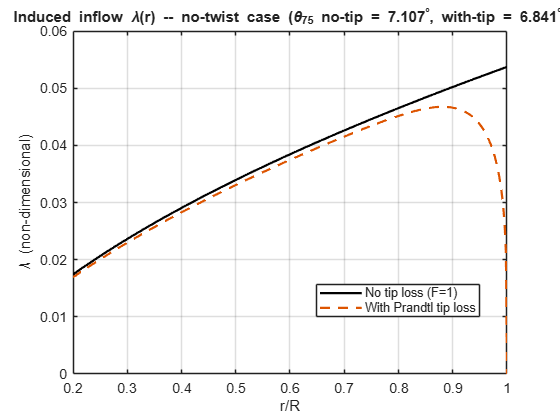


% obtain detailed distributions
[T_tip, lambda_tip, dTdr_tip, dQdr_total_tip, dQdr_ind_tip, dQdr_prof_tip] = ...
    inner_bemt_theta75(theta75_with_tip,'with_tip', x, r, R, c_root, Nb, rho, Omega, C_l_alpha, Cdo, tol_lambda, max_iter_F);

%% -------------------- Convert to non-dimensional densities / cumulative C_Q --------------------
dCTdr_no_tip = dTdr_no_tip ./ denom_CT;       % nondim density
dCTdr_tip    = dTdr_tip    ./ denom_CT;

dCqdr_no_tip = dQdr_total_no_tip ./ denom_CQ;
dCqdr_tip    = dQdr_total_tip    ./ denom_CQ;

Cq_cum_no_tip = cumtrapz(r, dCqdr_no_tip);
Cq_cum_tip    = cumtrapz(r, dCqdr_tip);

%% -------------------- Plot 1: Induced inflow lambda(x) (compare no-tip vs with-tip) --------------------
figure('Name','Induced inflow \lambda vs r/R (no-tip vs tip-loss)','NumberTitle','off');
plot(x, lambda_no_tip, '-k', 'LineWidth', 1.6); hold on;
plot(x, lambda_tip, '--', 'LineWidth', 1.6);
xlabel('r/R'); ylabel('\lambda (non-dimensional)'); grid on;
legend({'No tip loss (F=1)', 'With Prandtl tip loss'}, 'Location','best');
title(sprintf('Induced inflow \\lambda(r) -- no-twist case (\\theta_{75} no-tip = %.3f^\\circ, with-tip = %.3f^\\circ)', theta75_no_tip, theta75_with_tip));
xlim([x_root 1]);

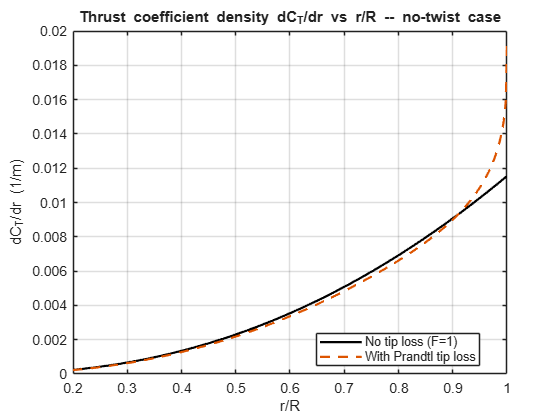


%% -------------------- Plot 2: Thrust distribution dC_T/dr (compare) --------------------
figure('Name','dC_T/dr vs r/R (no-tip vs tip-loss)','NumberTitle','off');
plot(x, dCTdr_no_tip, '-k', 'LineWidth', 1.6); hold on;
plot(x, dCTdr_tip, '--', 'LineWidth', 1.6);
xlabel('r/R'); ylabel('dC_T/dr (1/m)'); grid on;
legend({'No tip loss (F=1)', 'With Prandtl tip loss'}, 'Location','best');
title('Thrust coefficient density dC_T/dr vs r/R -- no-twist case');
xlim([x_root 1]);

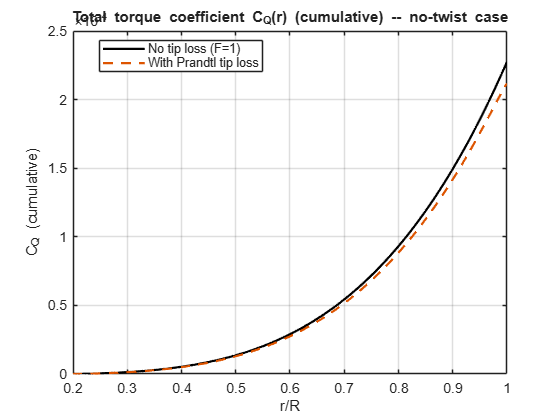


%% -------------------- Plot 3: Total torque coefficient C_Q(r) (cumulative) --------------------
figure('Name','Total C_Q(r) vs r/R (no-tip vs tip-loss)','NumberTitle','off');
plot(x, Cq_cum_no_tip, '-k', 'LineWidth', 1.6); hold on;
plot(x, Cq_cum_tip, '--', 'LineWidth', 1.6);
xlabel('r/R'); ylabel('C_Q (cumulative)'); grid on;
legend({'No tip loss (F=1)', 'With Prandtl tip loss'}, 'Location','best');
title('Total torque coefficient C_Q(r) (cumulative) -- no-twist case');
xlim([x_root 1]);


%% -------------------- Print comparison summary --------------------
fprintf('\nComparison summary (no-twist case):\n');


Comparison summary (no-twist case):


fprintf('  theta75 (no-tip)  = %.6f deg\n', theta75_no_tip);

  theta75 (no-tip)  = 7.106524 deg


fprintf('  theta75 (with-tip)= %.6f deg\n', theta75_with_tip);

  theta75 (with-tip)= 6.840922 deg


fprintf('  Thrusts achieved (sanity): T_no_tip = %.6f N, T_with_tip = %.6f N\n', T_no_tip, T_tip);

  Thrusts achieved (sanity): T_no_tip = 300.000000 N, T_with_tip = 300.000000 N



[~, idx75] = min(abs(x - 0.75));
fprintf('\nValues at r/R = 0.75:\n');


Values at r/R = 0.75:


fprintf('  lambda_no_tip = %.6e, lambda_with_tip = %.6e\n', lambda_no_tip(idx75), lambda_tip(idx75));

  lambda_no_tip = 4.456073e-02, lambda_with_tip = 4.339989e-02


fprintf('  dCTdr_no_tip = %.6e, dCTdr_with_tip = %.6e\n', dCTdr_no_tip(idx75), dCTdr_tip(idx75));

  dCTdr_no_tip = 5.952000e-03, dCTdr_with_tip = 5.667477e-03


fprintf('  C_Q_no_tip (at R) = %.6e, C_Q_with_tip (at R) = %.6e\n', Cq_cum_no_tip(end), Cq_cum_tip(end));

  C_Q_no_tip (at R) = 2.276209e-04, C_Q_with_tip (at R) = 2.116008e-04



%% ================= Local function: inner_bemt_theta75 (fully argumentized) =================
function [T, lambda_x, dTdr, dQdr_total, dQdr_ind, dQdr_prof] = inner_bemt_theta75(theta75_deg, mode, x, r, R, c_root, Nb, rho, Omega, C_l_alpha, Cdo, tol_lambda, max_iter_F)
    % Compute thrust and per-radius distributions for given constant theta75 (no twist case)
    % mode: 'no_tip' -> F=1, 'with_tip' -> iterate Prandtl tip-loss
    theta75_rad = deg2rad(theta75_deg);
    theta_x = theta75_rad .* ones(size(x));   % no twist
    c_x = c_root .* ones(size(x));
    sigma_x = Nb .* c_x ./ (pi * R);

    % Closed-form lambda from F and theta: lambda = sigma*Clalpha/16 * ( sqrt(1 + 32*F*theta*x/(sigma*Clalpha)) - 1 )
    lambda_from_F_theta = @(sigma, theta_loc, F_loc, x_loc, Clalpha) ( sigma .* Clalpha ./ 16 .* ( sqrt(1 + (32 .* F_loc .* theta_loc .* x_loc) ./ (sigma .* Clalpha) ) - 1 ) );

    % initialize with F = 1
    F = ones(size(x));
    lambda_old = lambda_from_F_theta(sigma_x, theta_x, F, x, C_l_alpha);

    if strcmp(mode,'with_tip')
        for it = 1:max_iter_F
            % compute phi and sin(phi)
            phi = atan( lambda_old ./ x );     % rad
            sinphi = sin(phi);
            % avoid zero or extremely small sinphi -> clamp
            sinphi(sinphi < 1e-12) = 1e-12;

            f_val = (Nb/2) .* ((1 - x) ./ (x .* sinphi)); % dimensionless
            % compute F (clamp to [0,1])
            F_new = (2/pi) .* acos( exp(-f_val) );
            F_new(F_new < 0) = 0;
            F_new(F_new > 1) = 1;

            lambda_new = lambda_from_F_theta(sigma_x, theta_x, F_new, x, C_l_alpha);

            maxdiff = max(abs(lambda_new - lambda_old));
            lambda_old = lambda_new;
            F = F_new;
            if maxdiff < tol_lambda
                break;
            end
        end
        lambda_x = lambda_old;
    else
        lambda_x = lambda_old;
    end

    % compute Cl and dT/dr from BET (use lambda_x for inflow term)
    Cl_x = C_l_alpha .* (theta_x - lambda_x ./ x);
    U2 = (Omega .* r).^2;
    dTdr = 0.5 .* rho .* Nb .* U2 .* Cl_x .* c_x;   % N/m

    % profile torque density dQp/dr
    dQdr_prof = r .* (0.5 .* rho .* Nb .* U2 .* c_x .* Cdo); % N*m per m

    % induced torque density dQi/dr = (dT/dr) * lambda * R
    dQdr_ind = dTdr .* lambda_x .* R;

    % total torque density
    dQdr_total = dQdr_prof + dQdr_ind;

    % total thrust
    T = trapz(r, dTdr);
end
